# 2021-03-09-Rena-m6A-KD-test

## KD

run_id = "max";

% input_path = 'D:/2021-03-09-Rena-m6A-KD-test/KD_2D/';
% reg_block = [12 5];

input_path = 'D:/2021-03-09-Rena-m6A-KD-test/WT_2D/';
reg_block = [6 10];

useGPU = true;

curr_out_path = fullfile(input_path, 'output', run_id)

curr_out_path = "D:\2021-03-09-Rena-m6A-KD-test\WT_2D\output\max"


if ~exist(curr_out_path, 'dir')
    mkdir(curr_out_path)
end
           
sdata_start = tic;
sdata = new_STARMapDataset(input_path, 'useGPU', useGPU);

Pipeline Obj is generated...


sdata.log = fopen(fullfile(curr_out_path, 'log.txt'), 'w');
sdata = sdata.LoadRawImages('output_class', "cell");

====Loading raw images====
Loading round 1...[time = 4.17 s]
Loading round 2...[time = 4.21 s]
Collapsed to size 5661 by 9260 by 1
Collapsing round 1
Collapsing round 2
Raw image as cell


for i=1:2
    sdata.rawImages{i} = uint8(sdata.rawImages{i});
end

sdata.rawImages = im_cell2mat(sdata.rawImages);
sdata = sdata.SwapChannels; % !!

====Swap Channels====
Channel 2 <==> Channel 3


sdata.registeredImages = im_cell2mat(new_JointRegister2D( im_mat2cell(sdata.rawImages), reg_block, 0));

Using block size of 943.000000 x 926.000000 
--------------------
Registering round [2 / 2] [time=0.109129]
Shifting by -4  10
Shifting (1 1) by -7  3
Shifting (1 2) by -8  5
Shifting (1 3) by -7  7
Shifting (1 4) by -8  7
Shifting (1 5) by -7  9
Shifting (1 6) by -7  11
Shifting (1 7) by -8  12
Shifting (1 8) by -7  14
Shifting (1 9) by -7  15
Shifting (1 10) by -7  16
Shifting (2 1) by -5  3
Shifting (2 2) by -6  4
Shifting (2 3) by -6  6
Shifting (2 4) by -6  7
Shifting (2 5) by -5  9
Shifting (2 6) by -5  11
Shifting (2 7) by -5  12
Shifting (2 8) by -6  13
Shifting (2 9) by -6  15
Shifting (2 10) by -5  17
Shifting (3 1) by -4  4
Shifting (3 2) by -4  4
Shifting (3 3) by -3  6
Shifting (3 4) by -4  9
Shifting (3 5) by -4  9
Shifting (3 6) by -5  10
Shifting (3 7) by -5  13
Shifting (3 8) by -4  14
Shifting (3 9) by -5  15
Shifting (3 10) by -5  16
Shifting (4 1) by -3  4
Shifting (4 2) by -2  4
Shifting (4 3) by -3  5
Shifting (4 4) by -3  8
Shifting (4 5) by -2  9
Shifting (4 6) 

sdata = sdata.xxx_LocalRegistration('Iterations', 50, 'AccumulatedFieldSmoothing', 1);

====Local (Non-rigid) Registration====
[time = 1.06 s]
Round 2 vs. Round 1...[time = 11.24 s]


sdata = sdata.LoadCodebook('doReverse', false);

====Load Codebook====
doReverse: 0


sdata = sdata.SpotFinding('Method', "ex_max3d", 'ref_index', 1,  'qualityThreshold', 0.5, ...
        'volumeThreshold', 30, 'barcodeMethod', "iteration", 'showPlots', false);

====Spot Finding====
Method: ex_max3d
Reference round: 1
Number of spots found by ex_max3d: 102442
[time = 36.85 s]


sdata = sdata.ReadsExtraction('showPlots', false, 'voxelSize', [2 2 1]); 

====Reads Extraction====
voxel size: 2 x 2 x 1
Geting color sequence for each voxel...

Geting max color...
445 
Decoding...

0.995275 [101958 / 102442] percent of reads are below score thresh 5.000000e-01


sdata = sdata.ReadsFiltration('showPlots', false);

====Reads Filtration====
mode: regular
Base in both ends: C --- C
Filtration Statistics:
0.171208 [17456 / 101958] percent of good reads are CNNNNNC
0.449411 [45821 / 101958] percent of good reads are in codebook
2.624943 [45821 / 17456] percent of CNNNNNC reads are in codebook


fclose(sdata.log);

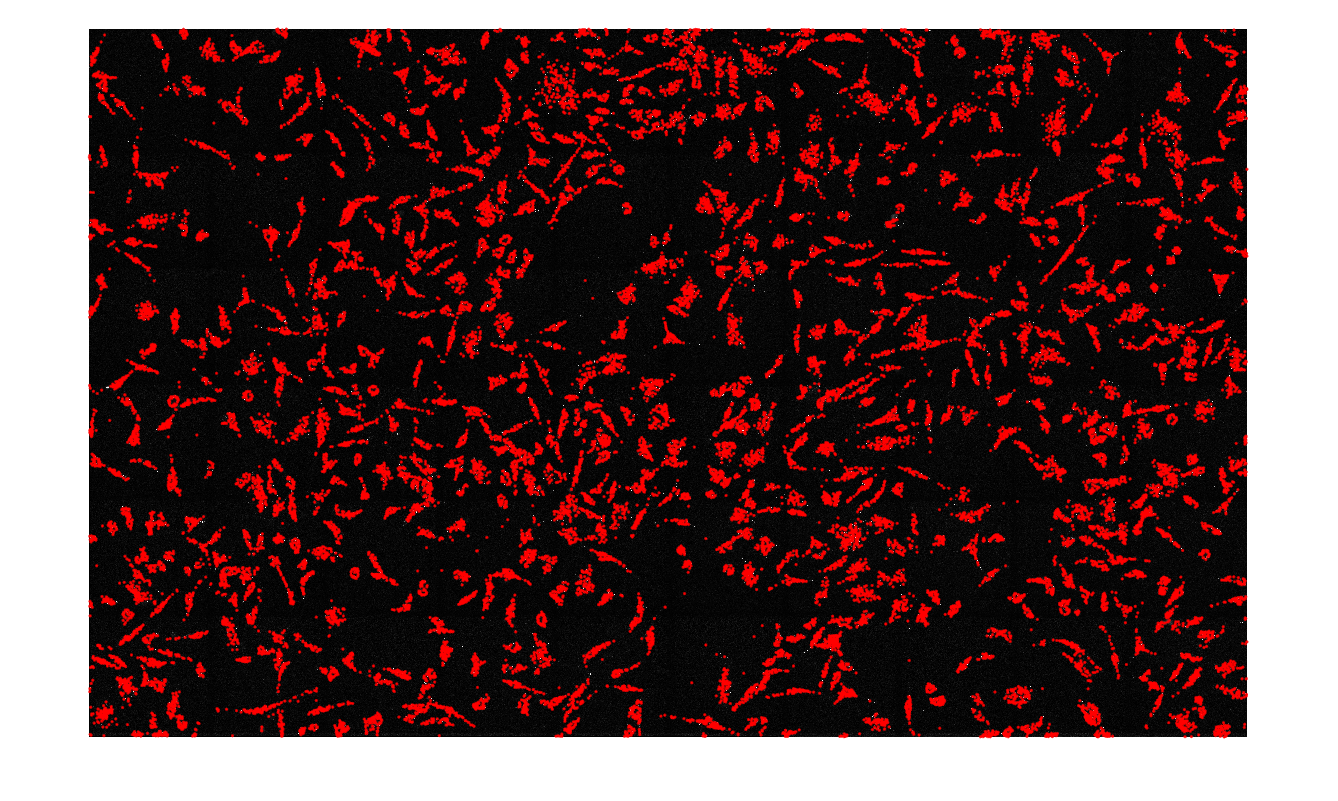

img = max(sdata.registeredImages(:,:,:,:,1), [], 4);
plot_centroids(sdata.goodSpots, img, 5, 'r')

goodSpots = sdata.goodSpots;
goodReads = sdata.goodReads;
goodReads = cellfun(@(x) sdata.seqToGene(x), goodReads, 'UniformOutput', false);
fname = fullfile(input_path, 'genes.csv');
f = readmatrix(fname, 'OutputType', 'string', "Delimiter", ',');
geneTonum = containers.Map(f(:,1), 1:size(f,1));
a = keys(geneTonum);
b = values(geneTonum);
goodReads = cellfun(@(x) geneTonum(x), goodReads);

save(fullfile(curr_out_path, 'goodPoints_max3d.mat'), "goodSpots", "goodReads");